# MXB161 Group 18 Project

## G'day

Add your name in the box below to verify you got your MATLAB setup with GitHub

% Josh
% Vlad
% Andrew
% Vlad 2nd test
% new stuff by Vlad

Some tips for working with Git in MATLAB

## **Commit Modified Files**

To record and save the current state of new and modified files in your working folder, commit them to your local repository.

To commit files to your local repository:

- In the Current Folder browser, right-click and select **Source Control** > **View and Commit Changes**. The View and Commit Changes dialog box opens.

- Select the files to commit.

- Enter a comment in the **Comment** section.

- Click the **Commit** button.

If the remote repository has moved ahead, you are prompted to update the revision of your files. To update the revision, right-click in the Current Folder browser and select **Source Control** > **Pull**. Resolve any conflicts before you commit.

## **Push Files**

If your local repository contains committed changes that are not in your remote repository, you can push those changes to your remote repository. To check whether your local repository contains changes that are not in your remote repository, right-click in the Current Folder browser and select **Source Control** > **View Details**. The **Git information** field indicates whether your committed local changes are ahead of, behind, or coincident with the remote repository.

If your local repository is ahead of your remote repository, to push the changes, right-click in the Current Folder browser and select **Source Control** > **Push**. A message appears if you cannot push your changes directly because the repository has moved on. To continue, pull the latest changes from the remote repository into your local repository.

Length = 100; %Length of the total area
Width = 100; %Width of the total area
N = 50; %Number of iterations
Area_array = zeros(Width,Length,N); %
% setting fire location manually for testing purposes.
Area_array(10,10,1) = 1;
figure(Visible=true), imshow(~Area_array(:,:,1),InitialMagnification="fit")
hold on
% for loop 
for iteration = 1:N 
    for y = 1:Length
        for x = 1:Width
            if x > 1 && x < Width && y > 1 && y < Length && x < Width
               if check_if_in_range_function(Area_array,iteration,x,y)
                  Area_array(x,y,iteration+1) = 1;
               end
            end
        end
    end
end

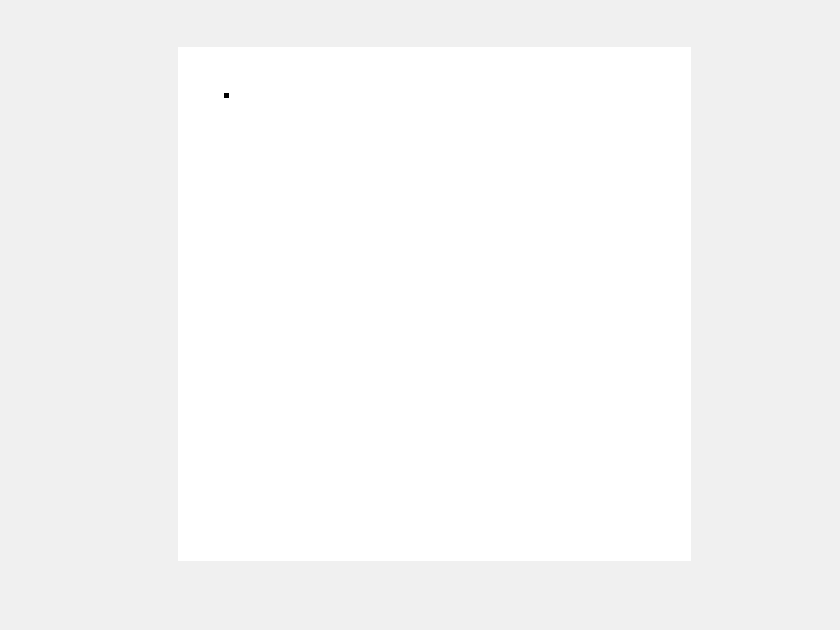

figure(Visible=true)
for i=1:N

    imshow(~Area_array(:,:,i),InitialMagnification="fit")
    drawnow
    hold on
end

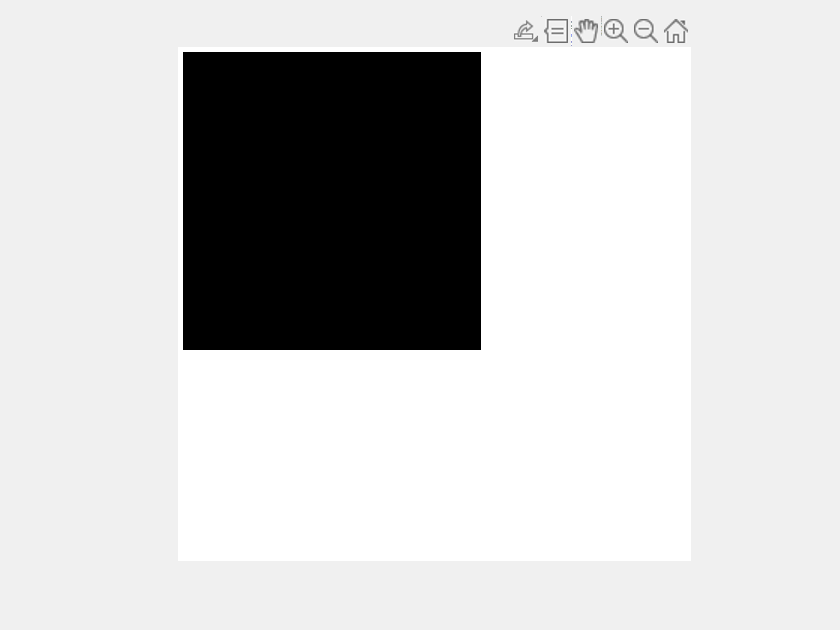

function [is_in_range] = check_if_in_range_function(space,n,current_x,current_y)
    if space(current_x-1, current_y+1, n) == 1
        is_in_range = 1;
    elseif space(current_x, current_y+1, n) == 1
        is_in_range = 1;
    elseif space(current_x+1, current_y+1, n) == 1
        is_in_range = 1;

    elseif space(current_x-1, current_y, n) == 1
        is_in_range = 1;
    elseif space(current_x, current_y, n) == 1
        is_in_range = 1;
    elseif space(current_x+1, current_y, n) == 1
        is_in_range = 1;


    elseif space(current_x-1, current_y-1, n) == 1
        is_in_range = 1;
    elseif space(current_x, current_y-1, n) == 1
        is_in_range = 1;
    elseif space(current_x+1, current_y-1, n) == 1
        is_in_range = 1;
    else
        is_in_range = 0;
    end
end